## Quiz 5 Practice : Numerical Integration Practice

1) (50%) For the function:


$$\frac{d^2 w}{{\textrm{dx}}^2 }={3x}^2 +4\;,\;\;\;\frac{\textrm{dw}\left(0\right)}{\textrm{dx}}=0,w\left(0\right)=1$$
 

a) (10%) Write the above differential equation as a state system and it's derivative.

Step 1: Identify

- Let s1 = w (the original function, the letetr on the top part of the fraction after "d")

- Let s2 = dw/dx (the first derivative)

Step 2:  The System

$\frac{\textrm{ds1}}{\textrm{dx}}=\frac{\textrm{dw}}{\textrm{dx}}=\textrm{s2}$      AND    $\frac{\textrm{ds2}}{\textrm{dx}}=\frac{d^2 w}{{\textrm{dx}}^2 }=3x^2 +4$  

Step 3: In vector Form


$$s=\left\lbrack \begin{array}{c}
w\\
\frac{\textrm{dw}}{\textrm{dx}}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack$$



$$s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
3{s_2 }^2 +4
\end{array}\right\rbrack$$



$$s\;\left(0\right)=\left\lbrack \begin{array}{c}
w\left(0\right)\\
\frac{\textrm{dw}}{\textrm{dx}}\left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$$


b) (20%) Solve the above differential equation using MATLAB's built-in ODE solver (ODE45).

clear; clc; close all;

% % Step 1: Set Up  
t_span= [0 5];   % Time Range
s0= [1 ; 0] ;    % Initial Condition, careful of order


% % Step 2: System as Anonymous
% (The system corresponds to S', so use vector form as reference) 
f = @(x, s) [s(2) ; ...  % First equation
             3*x^2 + 4]; % Second equation


% % Step 3: Apply ODE45
[x, s] = ode45(f, t_span, s0);

c) (20%)  Plot the result for $w\left(x\right)$ for x=0 to 5 from (b). Find the analytical solution using the Symbolic Toolbox and plot it alongside the previous result as well.

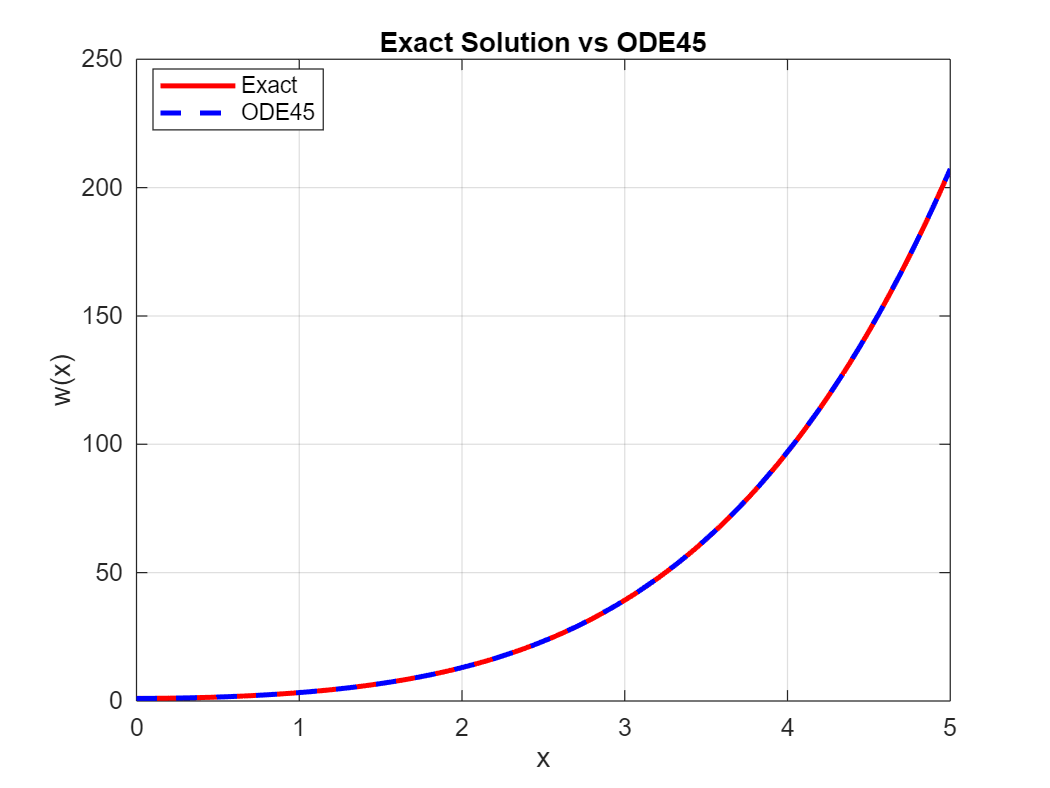

% % Step 4: Exact/Analytical Solution
syms wa(xa); % symbolic rep for  w(x)
eqn = diff(wa, xa, 2) == 3*xa^2 + 4; % defines the differential equation
Dwa = diff(wa, xa); % symbolic rep for the first derivative
cond = [wa(0) == 1, Dwa(0) == 0]; % Initial conditions : w(0) = 1 and w'(0) = 0.
wSol(xa) = dsolve(eqn, cond); % computes the exact solution

% % Step 5: Plotting
figure;
xx = linspace(0, 5); % for a smoothness
plot(xx, wSol(xx), 'r', 'LineWidth', 2); % exact
hold on;
plot(x, s(:, 1), '--b', 'LineWidth', 2); % ode45
hold off;
ylabel('w(x)'); % use "x" instead of t to make more sense
xlabel('x'); % again ^
title('Exact Solution vs ODE45');
legend('Exact','ODE45', 'Location', 'Best');
grid on; 

2) (50%) A drug affects the body in this inclusive way when starting a 20 mg pill.


$$\frac{\textrm{dx}}{\textrm{dt}}=-0\ldotp 090x\left(t\right)+0\ldotp 028y\left(t\right)-0\ldotp 007z\left(t\right)$$



$$\frac{\textrm{dy}}{\textrm{dt}}=\;\;\;\;0\ldotp 066x\left(t\right)-0\ldotp 038y\left(t\right)-0\ldotp 021z\left(t\right)$$



$$\frac{\textrm{dz}}{\textrm{dt}}=\;\;\;\;0\ldotp 060x\left(t\right)-0\ldotp 008y\left(t\right)-0\ldotp 01z\left(t\right)$$


Where x is the amount in the blood, y is the amount in the stomach and z is the amount in the body. We assume the blood and body are empty of the drug initially.

a) (10%) Write the above differential equations as a state system and its derivative.

Step 1: Identify

- Let s1 = x(t)  % #  in blood

- Let s2 = y(t) % # in stomach

- Let s3 = z(t) % # in rest of body

Step 2:  The System


$$\frac{ds_1 }{dt}=-0\ldotp 090s_1 +0\ldotp 028s_2 -0\ldotp 007s_3$$



$$\frac{ds_2 }{dt}=0\ldotp 066s_1 -0\ldotp 038s_2 -0\ldotp 021s_3$$



$$\frac{ds_3 }{dt}=0\ldotp 060s_1 -0\ldotp 008s_2 -0\ldotp 010s_3$$


Step 3: In vector Form


$$s=\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{s1}\\
\textrm{s2}\\
\textrm{s3}
\end{array}\right\rbrack$$



$$s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } \\
{s_3 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x^{\prime } \\
y^{\prime } \\
z^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-0\ldotp 090s_1 +0\ldotp 028s_2 -0\ldotp 007s_3 \\
0\ldotp 066s_1 -0\ldotp 038s_2 -0\ldotp 021s_3 \\
0\ldotp 060s_1 -0\ldotp 008s_2 -0\ldotp 01s_3 
\end{array}\right\rbrack$$


$s=\left\lbrack \begin{array}{c}
x\left(0\right)\\
y\left(0\right)\\
z\left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
20\\
0
\end{array}\right\rbrack$  % y is # in stomatch whcih is where the drug will start

b) (20%) Solve and plot the interaction over 150 minutes using MATLAB's built in ODE Solver (ODE45).

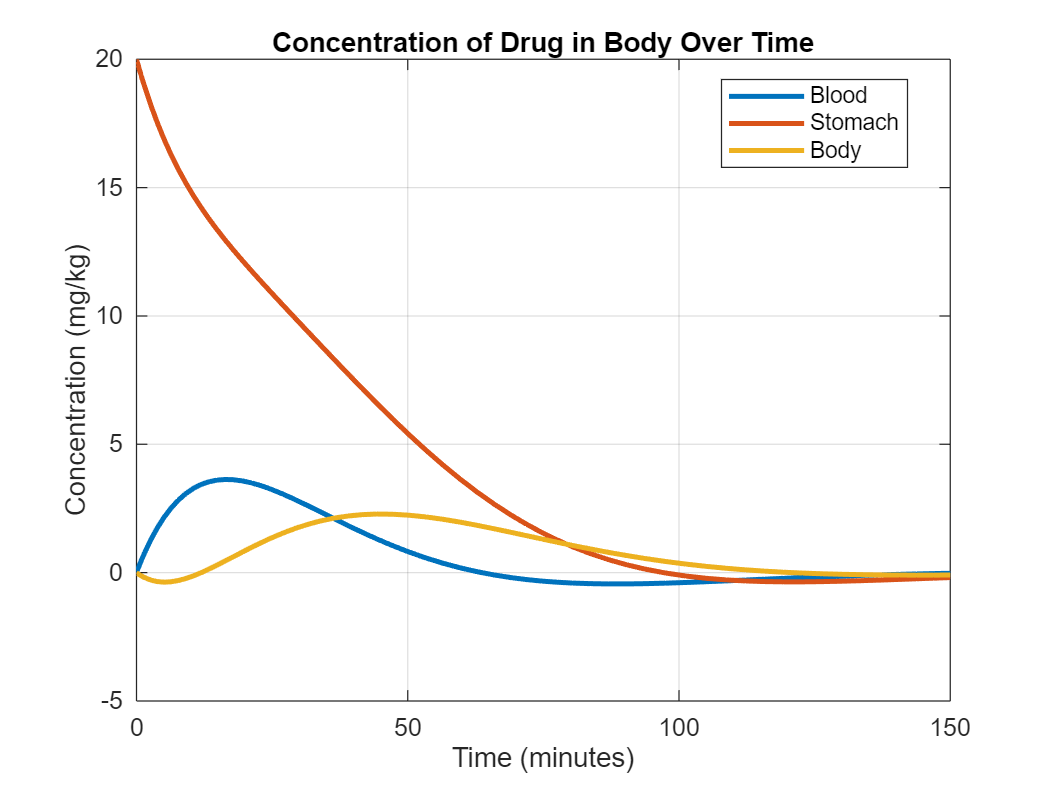

clear; clc; close all;

% % Step 1: Set Up  
t_span= [0 150];   % Time Range 0 - 150 minutes
s0= [0 ; 20 ; 0] ;    % Initial Condition, careful of order

% % Step 2: System as Anonymous
% (The system corresponds to S', so use vector form as reference) 
f = @(x, s) [-0.090*s(1) + 0.028*s(2) - 0.070*s(3) ; ...  % #  in blood
            0.066*s(1) - 0.038*s(2) - 0.021*s(3);... % # in stomach
            0.060*s(1) - 0.008*s(2) - 0.010*s(3)]; % # in rest of body


% % Step 3: Apply ODE45
[t, s] = ode45(f, t_span, s0);

% % Step 4: Plotting
figure;
plot(t, s, 'LineWidth', 2); % do not plot 3 times!!!!
xlabel('Time (minutes)');
ylabel('Concentration (mg/kg)');
title('Concentration of Drug in Body Over Time');
legend('Blood', 'Stomach', 'Body', 'Location', 'best');
grid on;

c) (20%) Find the time point for maximum amount of drug in the blood.

% Column 1 (s(:, 1)): Blood 
% Column 2 (s(:, 2)): Stomach
% Column 3 (s(:, 3)): Rest of the body 

[maxCB, maxCBtimeInt] = max(s(:,1));
disp(['Maximum concentration in Blood at t=: ', num2str(t(maxCBtimeInt)), ' m']);

Maximum concentration in Blood at t=: 16.2657 m


disp(['Maximum concentration in Blood: ', num2str(maxCB), ' mg/kg']);

Maximum concentration in Blood: 3.6284 mg/kg
